## **第10讲 线性方程（组）求解**

     线性方程组是线性代数研究的主要对象之一。求解线性方程组的问题不但在自然科学和工程技术中有所涉及，在计算方法的其他分支中，比如最佳平方逼近，微分方程数值解等，也往往需要求解线性方程组，因此它是一个应用相当广泛的分支。MATLAB软件最早也起源于对线性方程组的研究。

考虑线性代数方程

      $\textrm{Ax}=b$**（10-1）**

式中$A=\left\lbrack \begin{array}{cccc}
a_{11}  & a_{12}  & \cdots  & a_{1n} \\
a_{21}  & a_{22}  & \cdots  & a_{2n} \\
\vdots  & \vdots  & \ddots  & \vdots \\
a_{\textrm{m1}}  & a_{\textrm{m2}}  & \cdots  & a_{\textrm{mn}} 
\end{array}\right\rbrack$$\textrm{，b}=\left\lbrack \begin{array}{c}
b_1 \\
b_2 \\
\vdots \\
b_m 
\end{array}\right\rbrack$$\textrm{，x}=\left\lbrack \begin{array}{c}
x_1 \\
x_2 \\
\vdots \\
x_m 
\end{array}\right\rbrack$

这里不加证明地给出线性方程组的结构及判定定理

（1）当rank(A)=rank([A b])=n时，称方程组（10-1）为**恰定方程组**，这时它有**唯一解向量**。

（2）当rank(A)=rank([A b])<n时，称方程组（10-1）为**欠定方程组**，这时它有**无穷多组解向量**。

（3）当rank(A)<rank([A b])时，称方程组（10-1）为**超定方程组或者矛盾方程组**，一般意义下**无解**，但可以使用Moore-Penrose广义逆求出其**最小二乘解**

 对于恰定方程组的求解，线性代数的知识已经介绍了线性方程组求解的Cramer法则：当$\textrm{det}\left(A\right)\not= 0$时，方程组（10-1）有唯一解$c={\left(c_1 ,c_2 ,\cdots ,c_n \right)}^T$,并且

$c_i =\frac{\textrm{det}\left(B_i \right)}{\textrm{det}\left(A\right)}\;\;i=1,2,\cdots n$**                                      (10-2)**

    $B_i$是用$b$替换$A$的第$i$列$a_i$所得到的的矩阵。

**缺点：Cramer法则运算量太大。对于一个n阶方程组需要计算n+1个n阶行列式，而对n阶行列式若采用按行（或按列）展开来计算，至少需要进行**$n!$**次乘法，因此共需要进行**$\left(n+1\right)!$**次乘法。该算法对于n比较大的情形是不适用的。**

因此，必须研究其他数值算法。

 **重点学习：直接法和迭代法**。

**直接法**是在没有舍入误差的情况下，通过有限步四则运算可以求得方程组精确解的方法，但是在实际计算中由于舍入误差的存在和影响，该方法也只能求得线性方程组的近似解；

**迭代法**是用某种极限过程取逐步逼近准确解的方法，从而也可用有限步运算得出具有指定精确度的近似解。

### **10.1  消去法**

`我们将对``GAUSS消去法``和``追赶法``进行学习。`

`首先通过介绍上三角方程组的求解了解消去法的基本原理`

            $\begin{array}{l}
u_{11} x_1 +u_{12} x_2 +\ldotp \ldotp \ldotp +u_{1,n-1} x_{n-1} +u_{1,n} x_n =y_1 \\
u_{22} x_2 +\ldotp \ldotp \ldotp +u_{2,n-1} x_{n-1} +u_{2,n} x_n =y_2 \\
\ldotp \ldotp \ldotp \ldotp \ldotp \ldotp \\
u_{n-1,n-1} x_{n-1} +u_{n-1,n} x_n =y_{n-1} \\
u_{n,n} x_n =y_n 
\end{array}$**                                 (10-3)**

     我们称形如（10-3）的方程组为上三角形方程组，将其改写成矩阵的形式为

               $\textrm{Ux}=y$**                                                                                  (10-4)**

式中$U=\left\lbrack \begin{array}{ccccc}
u_{11}  & u_{12}  & \ldotp \ldotp \ldotp  & u_{1,n-1}  & u_{1,n} \\
 & u_{22}  & \ldotp \ldotp \ldotp  & u_{2,n-1}  & u_{2,n} \\
 &  & \ldotp \ldotp \ldotp  &  & \\
 &  &  & u_{n-1,n-1}  & u_{n-1,n} \\
 &  &  &  & u_{n,n} 
\end{array}\right\rbrack$                                                                                          

       
$$y=\left\lbrack \begin{array}{c}
y_1 \\
y_2 \\
\ldotp \ldotp \ldotp \\
y_{n-1} \\
y_n 
\end{array}\right\rbrack$$


称$U$为上三角矩阵

   若$\textrm{detU}\not= 0$ 则我们称上三角方程组（10-3）或者（10-4）有唯一解且解可从（10-3）最后一个方程得出

                  $x_n =y_n /u_{\textrm{nn}}$**                                                        (10-5)**

  代入倒数第二个方程可得$x_{n-1} =\left(y_n -u_{n-1,n} x_n \right)/u_{n-1,n-1}$

  通常设已知$x_n ,x_{n-1} \ldotp \ldotp \ldotp \ldotp x_{i+1}$则由方程组（5-3）的第$i$个方程可以得到

                   $x_i =\left\lbrack y_i -\sum_{j=i+1}^n u_{\textrm{ij}} x_j \right\rbrack /u_{\textrm{ii}} \left(i=n-1,n-2\cdots ,1\right)$**    （10-6）**

上述求解方程组（10-3）的过程称为**回代过程**。

#### **10.1.1 GAUSS消去法**

   GAUSS消去法主要包括**消元**和**迭代**两个步骤。

**消元**指的是将线性方程组化成与其同解的上三角方程组，**迭代**是指通过上三角方程组解出原方程组中的未知数。

这里介绍**顺序GAUSS消去法**和**列主元GAUSS消去法**

  **1.顺序高斯消去法**

    顺序Gauss消去法是指按照行原先的位置进行消元的Gauss消去法，

  将线性方程组（10-1）写成增广矩阵的形式

${\overset{-}{A} }^{\left(1\right)} =\left\lbrack A\;\;\;b\right\rbrack =\left\lbrack \begin{array}{ccccc}
{a_{11} }^{\mathrm{（1）}}  & {a_{12} }^{\mathrm{（1）}}  & \cdots  & {a_{1n} }^{\mathrm{（1）}}  & {a_{1,n+1} }^{\mathrm{（1）}} \\
{a_{21} }^{\mathrm{（1）}}  & {a_{22} }^{\mathrm{（1）}}  & \cdots  & {a_{2n} }^{\mathrm{（1）}}  & {a_{2,n+1} }^{\mathrm{（1）}} \\
\vdots  & \vdots  & \ddots  & \vdots  & \vdots \\
{a_{n1} }^{\mathrm{（1）}}  & {a_{\mathrm{n2}} }^{\mathrm{（1）}}  & \cdots  & {a_{\mathrm{nn}} }^{\mathrm{（1）}}  & {a_{n,n+1} }^{\mathrm{（1）}} 
\end{array}\right\rbrack$ **（10-7）**

式中${a_{\mathrm{ij}} }^{\mathrm{（1）}} =a_{\mathrm{ij}} ,{a_{i\ldotp n+1} }^{\mathrm{（1）}} =b_i \;\;\;\;\;\;\;\left(1\le i,j\le n\right)$

**A.消元过程**


$$\begin{array}{l}
{\overset{-}{A} }^{\left(1\right)} =\left\lbrack A\;\;\;b\right\rbrack =\left\lbrack \begin{array}{ccccc}
{a_{11} }^{\mathrm{（1）}}  & {a_{12} }^{\mathrm{（1）}}  & \cdots  & {a_{1n} }^{\mathrm{（1）}}  & {a_{1,n+1} }^{\mathrm{（1）}} \\
{a_{21} }^{\mathrm{（1）}}  & {a_{22} }^{\mathrm{（1）}}  & \cdots  & {a_{2n} }^{\mathrm{（1）}}  & {a_{2,n+1} }^{\mathrm{（1）}} \\
\vdots  & \vdots  & \ddots  & \vdots  & \vdots \\
{a_{n1} }^{\mathrm{（1）}}  & {a_{\mathrm{n2}} }^{\mathrm{（1）}}  & \cdots  & {a_{\mathrm{nn}} }^{\mathrm{（1）}}  & {a_{n,n+1} }^{\mathrm{（1）}} 
\end{array}\right\rbrack =\left\lbrack A\;\;\;\;b\right\rbrack \;\;\;\;\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;
\end{array}$$


$\begin{array}{l}
l_{\mathrm{i1}} =\frac{{a_{\mathrm{i1}} }^{\left(1\right)} }{{a_{11} }^{\left(1\right)} }\left(i=2,3\ldotp \ldotp \ldotp n\right)\\
{a_{\mathrm{ij}} }^{\left(2\right)} ={a_{\mathrm{ij}} }^{\left(1\right)} -l_{\mathrm{i1}} {a_{1j} }^{\left(1\right)} \left(i,j=2,3\ldotp \ldotp \ldotp \ldotp n\right)
\end{array}$        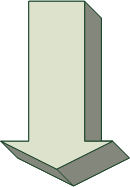


$${\overset{-}{A} }^{\left(2\right)} =\left\lbrack A\;\;\;b\right\rbrack =\left\lbrack \begin{array}{ccccc}
{a_{11} }^{\mathrm{（1）}}  & {a_{12} }^{\mathrm{（1）}}  & \cdots  & {a_{1n} }^{\mathrm{（1）}}  & {a_{1,n+1} }^{\mathrm{（1）}} \\
0 & {a_{22} }^{\mathrm{（2）}}  & \cdots  & {a_{2n} }^{\mathrm{（2）}}  & {a_{2,n+1} }^{\mathrm{（2）}} \\
\vdots  & \vdots  & \ddots  & \vdots  & \vdots \\
0 & {a_{\mathrm{n2}} }^{\mathrm{（2）}}  & \cdots  & {a_{\mathrm{nn}} }^{\mathrm{（2）}}  & {a_{n,n+1} }^{\mathrm{（2）}} 
\end{array}\right\rbrack \;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;$$


$\begin{array}{l}
l_{\mathrm{i2}} =\frac{{a_{\mathrm{i2}} }^{\left(2\right)} }{{a_{22} }^{\left(2\right)} }\left(i=3,4\ldotp \ldotp \ldotp n\right)\\
{a_{\mathrm{ij}} }^{\left(3\right)} ={a_{\mathrm{ij}} }^{\left(2\right)} -l_{\mathrm{i2}} {a_{2j} }^{\left(2\right)} \left(i,j=3,4\ldotp \ldotp \ldotp \ldotp n\right)
\end{array}$


$$\;\;\;{\overset{-}{A} }^{\left(3\right)} =\left\lbrack A\;\;\;b\right\rbrack =\left\lbrack \begin{array}{ccccc}
{a_{11} }^{\mathrm{（1）}}  & {a_{12} }^{\mathrm{（1）}}  & \cdots  & {a_{1n} }^{\mathrm{（1）}}  & {a_{1,n+1} }^{\mathrm{（1）}} \\
0 & {a_{22} }^{\mathrm{（2）}}  & {a_{23} }^{\mathrm{（2）}} \cdots  & {a_{2n} }^{\mathrm{（2）}}  & {a_{2,n+1} }^{\mathrm{（2）}} \\
\vdots  & \vdots  & \vdots  & \vdots  & \vdots \\
0 & 0 & {a_{\mathrm{n3}} }^{\mathrm{（3）}}  & {a_{\mathrm{nn}} }^{\mathrm{（3）}}  & {a_{n,n+1} }^{\mathrm{（3）}} 
\end{array}\right\rbrack \;\;\;\;\;\;$$



$$\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\vdots$$



$$\begin{array}{l}
{\overset{-}{A} }^{\left(k\right)} =\left\lbrack \begin{array}{cccccccc}
{a_{11} }^{\left(1\right)}  & \cdots  & {a_{1,k-1} }^{\left(1\right)}  & {a_{1,k} }^{\left(1\right)}  & {a_{1,k+1} }^{\left(1\right)}  & \cdots  & {a_{1n} }^{\left(1\right)}  & {a_{1,n+1} }^{\left(1\right)} \\
\vdots  & \ddots  & \vdots  & \vdots  & \vdots  & \ddots  & \vdots  & \vdots \\
0 & \cdots  & {a_{k-1,k-1} }^{\left(k-1\right)}  & {a_{k-1,k} }^{\left(k-1\right)}  & {a_{k-1,k} }^{\left(k-1\right)}  & \cdots  & {a_{k-1,n} }^{\left(k-1\right)}  & {a_{k-1,n+1} }^{\left(k-1\right)} \\
0 & \cdots  & 0 & {a_{\mathrm{kk}} }^{\left(k\right)}  & {a_{k,k+1} }^{\left(k\right)}  & \cdots  & {a_{\mathrm{kn}} }^{\left(k\right)}  & {a_{k,n+1} }^{\left(k\right)} \\
0 & \cdots  & 0 & {a_{k+1,k} }^{\left(k\right)}  & {a_{k+1,k+1} }^{\left(k\right)}  & \cdots  & {a_{k+1,n} }^{\left(k\right)}  & {a_{k+1,n+1} }^{\left(k\right)} \\
\vdots  & \ddots  & \vdots  & \vdots  & \vdots  & \ddots  & \vdots  & \vdots \\
0 & 0 & 0 & {a_{\mathrm{nk}} }^{\left(k\right)}  & {a_{n,k+1} }^{\left(k\right)}  & \cdots  & {a_{\mathrm{nn}} }^{\left(k\right)}  & {a_{n,n+1} }^{\left(k\right)} 
\end{array}\right\rbrack \\
\;\;
\end{array}$$


$\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\begin{array}{l}
l_{\mathrm{ik}} =\frac{{a_{\mathrm{ik}} }^{\left(k\right)} }{{a_{\mathrm{kk}} }^{\left(k\right)} }\left(i=k+1\ldotp \ldotp \ldotp n\right)\\
{a_{\mathrm{ij}} }^{\left(k+1\right)} ={a_{\mathrm{ij}} }^{\left(k\right)} -l_{\mathrm{ik}} {a_{\mathrm{kj}} }^{\left(k\right)} \left(i,j=k+1\ldotp \ldotp \ldotp \ldotp n\right)
\end{array}\;\;\;$


$${\overset{-}{A} }^{\left(k+1\right)} =\left\lbrack \begin{array}{cccccccc}
{a_{11} }^{\left(1\right)}  & \cdots  & {a_{1,k-1} }^{\left(1\right)}  & {a_{1,k} }^{\left(1\right)}  & {a_{1,k+1} }^{\left(1\right)}  & \cdots  & {a_{1n} }^{\left(1\right)}  & {a_{1,n+1} }^{\left(1\right)} \\
\vdots  & \ddots  & \vdots  & \vdots  & \vdots  & \ddots  & \vdots  & \vdots \\
0 & \cdots  & {a_{k-1,k-1} }^{\left(k-1\right)}  & {a_{k-1,k} }^{\left(k-1\right)}  & {a_{k-1,k} }^{\left(k-1\right)}  & \cdots  & {a_{k-1,n} }^{\left(k-1\right)}  & {a_{k-1,n+1} }^{\left(k-1\right)} \\
0 & \cdots  & 0 & {a_{\mathrm{kk}} }^{\left(k\right)}  & {a_{k,k+1} }^{\left(k\right)}  & \cdots  & {a_{\mathrm{kn}} }^{\left(k\right)}  & {a_{k,n+1} }^{\left(k\right)} \\
0 & \cdots  & 0 & 0 & {a_{k+1,k+1} }^{\left(k+1\right)}  & \cdots  & {a_{k+1,n} }^{\left(k+1\right)}  & {a_{k+1,n+1} }^{\left(k+1\right)} \\
\vdots  & \ddots  & \vdots  & \vdots  & \vdots  & \ddots  & \vdots  & \vdots \\
0 & 0 & 0 & 0 & {a_{n,k+1} }^{\left(k+1\right)}  & \cdots  & {a_{\mathrm{nn}} }^{\left(k+1\right)}  & {a_{n,n+1} }^{\left(k+1\right)} 
\end{array}\right\rbrack \;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;$$


通常称$l_{\textrm{ik}}$为消元因子，称${a_{\textrm{kk}} }^{\left(k\right)}$为主元

B.回代过程

根据上述消元过程所得的结果可以根据式（10-5）和式（10-6）求得线性方程组的解。

  $x_n =y_n /u_{\textrm{nn}}$**  (10-5)**

  $x_i =\left\lbrack y_i -\sum_{j=i+1}^n u_{\textrm{ij}} x_j \right\rbrack /u_{\textrm{ii}} \left(i=n-1,n-2\cdots ,1\right)$** （10-6）**

**---------------------- 程序实现 -----------------------------**

根据上面的消元和迭代过程，可以得到实现顺序Gauss消去法的程序Gauss.m，程序的具体内容如下：

`function [U,x]=Gauss(A,b)`

`% ``顺序``Gauss``消去法求解线性方程组`

`% ``输入参数：`

`%`      `---A``：线性方程组的系数矩阵`

`%`      `---b``：线性方程组的右端项`

`% ``输出参数：`

`%`      `---U``：消元后的上三角方程组的增广矩阵`

`%`      `---x``：线性方程组的解`

`n=length(b);`

`% ``消元过程`

`for k=1:n-1   % 消元成上三角矩阵`

    `m=A(k+1:n,k)/A(k,k);`

    `A(k+1:n,k+1:n)=A(k+1:n,k+1:n)-m*A(k,k+1:n);`

    `b(k+1:n)=b(k+1:n)-m*b(k);`

    `A(k+1:n,k)=zeros(n-k,1);`

`end`

`U=[A,b];`

`% ``回代过程`

`x=zeros(n,1);`

`x(n)=b(n)/A(n,n);`  `% ``求``x_n`

`for k=n-1:-1:1   % 回代`

    `x(k)=(b(k)-A(k,k+1:n)*x(k+1:n))/A(k,k);`  `% ``求``x_k``，``k=n-1,n-2,``…``,1`

`end`

`该函数的调用格式为[U,x]=Gauss(A,b)`

`------------------- 实例 ----------------------`

`【例10-1】利用顺序Gauss消去法求解下面的线性方程组`


$$\begin{array}{l}
x+2y+3z=1\\
4x+5y+6z=1\\
7x+8y=1
\end{array}$$


编写如下语句


A=[1 2 3;4 5 6;7 8 0];  % 线性方程组的系数矩阵
b=ones(3,1);  % 线性方程组的右端向量
[U,x] = Gauss(A,b);  % 利用顺序Gauss消去法求解线性方程组
U

U =      1     2     3     1
     0    -3    -6    -3
     0     0    -9     0


x

x =     -1
     1
     0


**2.列主元Gauss消去法**

 **顺序消去法缺点：在顺序消去法中必须满足**$a_{\textrm{kk}}^{\left(k\right)} \not= 0$**（**$\left.k=1,2,,,,n\right)$**否则将无法进行计算。**

**另外：即使**$a_{\textrm{kk}}^{\left(k\right)}$**=0 ，但如果其绝对值**$\left|a_{\textrm{kk}}^{\left(k\right)} \right|$**很小，那么由于舍入误差的影响，也可能引起很大的误差，从而使顺序Gauss消去法失效。**

 **解决这个问题的方法之一就是 —— 列主元消去法：**

实现过程为：选取列主元，当消元过程进行到第$k$步时，其相应的增广矩阵为


$${\overset{-}{A} }^{\left(k\right)} =\left\lbrack \begin{array}{cccccccc}
{a_{11} }^{\left(1\right)}  & \cdots  & {a_{1,k-1} }^{\left(1\right)}  & {a_{1,k} }^{\left(1\right)}  & {a_{1,k+1} }^{\left(1\right)}  & \cdots  & {a_{1n} }^{\left(1\right)}  & {a_{1,n+1} }^{\left(1\right)} \\
\vdots  & \ddots  & \vdots  & \vdots  & \vdots  & \ddots  & \vdots  & \vdots \\
0 & \cdots  & {a_{k-1,k-1} }^{\left(k-1\right)}  & {a_{k-1,k} }^{\left(k-1\right)}  & {a_{k-1,k} }^{\left(k-1\right)}  & \cdots  & {a_{k-1,n} }^{\left(k-1\right)}  & {a_{k-1,n+1} }^{\left(k-1\right)} \\
0 & \cdots  & 0 & {a_{\mathrm{kk}} }^{\left(k\right)}  & {a_{k,k+1} }^{\left(k\right)}  & \cdots  & {a_{\mathrm{kn}} }^{\left(k\right)}  & {a_{k,n+1} }^{\left(k\right)} \\
0 & \cdots  & 0 & {a_{k+1,k} }^{\left(k\right)}  & {a_{k+1,k+1} }^{\left(k\right)}  & \cdots  & {a_{k+1,n} }^{\left(k\right)}  & {a_{k+1,n+1} }^{\left(k\right)} \\
\vdots  & \ddots  & \vdots  & \vdots  & \vdots  & \ddots  & \vdots  & \vdots \\
0 & 0 & 0 & {a_{\mathrm{nk}} }^{\left(k\right)}  & {a_{n,k+1} }^{\left(k\right)}  & \cdots  & {a_{\mathrm{nn}} }^{\left(k\right)}  & {a_{n,n+1} }^{\left(k\right)} 
\end{array}\right\rbrack$$


按照Gauss消去法，应选择$a_{\textrm{kk}}^{\left(k\right)}$为主元，使得第$k$个方程不变。但注意到，此时第$k$个方程与之后的$n-k$个方程的地位并没有区别，选择第$k$列的元素$a_{\textrm{ik}}^{\left(k\right)}$($\left.i=k,k+1,\ldotp \ldotp \ldotp ,n\right)$中绝对值最大的元素作为主元，即令$\left|{a_{\textrm{rk}} }^{\left(k\right)} \right|=\max_{k\le i\le n} \left|{a_{\textrm{ik}} }^{\left(k\right)} \right|$

如果$a_{\textrm{rk}}^{\left(k\right)}$=0,则说明矩阵不可逆，即方程组的解不确定；否则当$r>k$时，则在增广矩阵中交换第$k$行与第$r$行，这时$a_{\textrm{rk}}^{\left(k\right)}$成为主元（此时变成了$a_{\textrm{kk}}^{\left(k\right)}$），然后再按Gauss消去法进行消元运算。

--------- 列主元消去法程序实现 ------------------

   根据上述过程。可以编写利用列主元Gauss消去法求解线性方程组解的程序Gauss_column.m，具体内容如下

`function [U,x]=Gauss_column(A,b)`

`% ``列主元``Gauss``消去法求解线性方程组`

`% ``输入参数：`

`%`      `---A``：线性方程组的系数矩阵`

`%`      `---b``：线性方程组的右端项`

`% ``输出参数：`

`%`      `---U``：消元后的上三角方程组的增广矩阵`

`%`      `---x``：线性方程组的解`

`n=length(b);`

`for k=1:(n-1)`

    `% ``选主元`

    `[Y,I]=max(abs(A(k:n,k)));  % 返回绝对值最大的a_kk的值和位置`

`    I=I+k-1;`

`    if I>k`

`        t=A(k,:); A(k,:)=A(I,:); A(I,:)=t;   % 交换第I行和第k行元素`

`        t=b(k); b(k)=b(I); b(I)=t;`

`    end`

    `% ``消元`

    `m=A(k+1:n,k)/A(k,k);`

    `A(k+1:n,k+1:n)=A(k+1:n,k+1:n)-m*A(k,k+1:n);`

    `b(k+1:n)=b(k+1:n)-m*b(k);`

    `A(k+1:n,k)=zeros(n-k,1);`

`end`

`U=[A,b];`

`% ``回代`

`x=zeros(n,1);`

`x(n)=b(n)/A(n,n);`

`for k=n-1:-1:1`

    `x(k)=(b(k)-A(k,k+1:n).*x(k+1:n))/A(k,k);`

`end`

`该函数的调用格式为[U,x]=Gauss_column(A,b)`

`------------- 示例 -------------------------`

`例【10-2】利用列主元Gauss消去法求解例【10-1】`

A=[1 2 3;4 5 6;7 8 0];  % 线性方程组的系数矩阵
b=ones(3,1);  % 线性方程组的右端向量
[U,x]=Gauss_column(A,b);  % 利用列主元Gauss消去法求解线性方程组
U

U =     7.0000    8.0000         0    1.0000
         0    0.8571    3.0000    0.8571
         0         0    4.5000   -0.0000


x

x =    -1.0000
    1.0000
   -0.0000


#### **10.1.2 追赶法**

在科学研究与工程计算中，经常遇到求解三对角方程组的问题：

   $\left\lbrack \begin{array}{ccccc}
b_1  & c_1  &  &  & \\
a_2  & b_2  & c_2  &  & \\
 & \ddots  & \ddots  & \ddots  & \\
 &  & a_{n-1}  & b_{n-1}  & c_{n-1} \\
 &  &  & a_n  & b_n 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x_1 \\
x_2 \\
\vdots \\
x_{n-1} \\
x_n 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
d_1 \\
d_2 \\
\vdots \\
d_{n-1} \\
d_n 
\end{array}\right\rbrack$**（10-8）**

将Gauss消去法应用于三对角方程组，即得到所谓的“**追赶法**”。追赶法的具体操作过程为


$$\left\lbrack \begin{array}{cccccc}
b_1  & c_1  &  &  &  & d_1 \\
a_2  & b_2  & b_2  &  &  & d_2 \\
 & \ddots  & \ddots  & \ddots  &  & \vdots \\
 &  & a_{n-1}  & b_{n-1}  & c_{n-1}  & d_{n-1} \\
 &  &  & a_n  & b_n  & d_n 
\end{array}\right\rbrack \Rightarrow \left\lbrack \begin{array}{ccccc}
\overset{-}{b_1 }  & c_1  &  &  & \overset{-}{d_1 } \\
 & \overset{-}{b_2 }  & c_2  &  & \overset{-}{d_2 } \\
 & \ddots  & \ddots  & \ddots  & \\
 &  & \overset{-}{b_{n-1} }  & c_{n-1}  & \overset{-}{d_{n-1} } \\
 &  &  & \overset{-}{b_n }  & \overset{-}{d_n } 
\end{array}\right\rbrack$$


式中


$$\begin{array}{l}
\overset{-}{b_1 } =\overset{-}{b} \;,\;\overset{-}{d_1 } =\overset{-}{d} \\
\overset{-}{b_k } =b_k -\frac{a_k }{b_{k-1} }c_{k-1} \left(k=2,3,\ldotp \ldotp \ldotp \ldotp n\right)\\
\overset{-}{d_k } =d_k -\frac{a_k }{b_{k-1} }\overset{-}{d_{k-1} } 
\end{array}$$


可解得


$$\begin{array}{l}
x_n =\frac{\overset{-}{d_n } }{\overset{-}{b_n } }\\
x_k =\frac{\overset{-}{d_k } -c_k x_{k+1} }{\overset{-}{b_k } }\\
\left(k=n-1,n-2,\cdots 1\right)
\end{array}$$


追赶法不需要对零元素进行计算，因此计算量较小，且当稀疏矩阵对角占优时数值稳定，是解三对角方程组的优秀算法。

--------- 程序实现 ----------------------

下面给出追赶法的MATLAB程序

`function [U,x]=Catch_up(a,b,c,d)`

`% ``追赶法求解三对角方程组`

`% ``输入参数：`

`%`      `---a``：次下对角线元素向量`

`%`      `---b``：主对角元素向量`

`%`      `---c``：次上对角线元素向量`

`%`      `---d``：右端向量`

`% ``输出参数：`

`%`      `---U``：消元后的上三角方程组的增广矩阵`

`%`      `---x``：三对角方程组的解`

`n=length(d);`

`% ``消元`

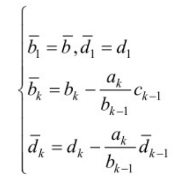

`for i=2:n`

`    l(i)=a(i-1)/b(i-1);   % 注意与公式的区别，向量的起始元素索引为1`

`    b(i)=b(i)-l(i)*c(i-1);`

`    d(i)=d(i)-l(i)*d(i-1);`

`end`

`U=[diag(b)+diag(c,1),d];    % 对角矩阵生成`

`% `

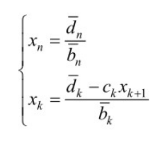

`x(n)=d(n)/b(n);`

`for i=n-1:-1:1`

    `x(i)=(d(i)-c(i)*x(i+1))/b(i);`

`end`

`该函数的调用格式为[U,x]=Catch_up(a,b,c,d)`

`----------  示例  ---------------------------`

`例【10-3】利用追赶法解下面的三对角方程组`


$$\left\lbrack \begin{array}{cccc}
-2 & 1 & 0 & 0\\
1 & -2 & 1 & 0\\
0 & 1 & -2 & 1\\
0 & 0 & 1 & -2
\end{array}\right\rbrack x=\left\lbrack \begin{array}{c}
1\\
0\\
0\\
0
\end{array}\right\rbrack$$


% 1、用追赶法解
a=ones(3,1);b=-2*ones(4,1);c=a;d=[1;0;0;0];  % 主对角线、次对角线和右端向量
tic
[U,x]=Catch_up(a,b,c,d)  % 利用追赶法求解三对角方程组

U =    -2.0000    1.0000         0         0    1.0000
         0   -1.5000    1.0000         0    0.5000
         0         0   -1.3333    1.0000    0.3333
         0         0         0   -1.2500    0.2500


x =    -0.8000   -0.6000   -0.4000   -0.2000


toc

历时 0.193514 秒。


% 2、直接用高斯消元法阶
A=diag(a,1)+diag(a,-1)+diag(b);  % 构造线性方程组的系数矩阵
tic
[U1,x1]=Gauss(A,d)  % 利用Gauss消去法进行检验

U1 =    -2.0000    1.0000         0         0    1.0000
         0   -1.5000    1.0000         0    0.5000
         0         0   -1.3333    1.0000    0.3333
         0         0         0   -1.2500    0.2500


x1 =    -0.8000
   -0.6000
   -0.4000
   -0.2000


toc

历时 0.047989 秒。


% 3、用列主元消元法解
A=diag(a,1)+diag(a,-1)+diag(b);  % 构造线性方程组的系数矩阵
tic
[U2,x2]=Gauss_column(A,d)  % 利用Gauss消去法进行检验

U2 =    -2.0000    1.0000         0         0    1.0000
         0   -1.5000    1.0000         0    0.5000
         0         0   -1.3333    1.0000    0.3333
         0         0         0   -1.2500    0.2500


x2 =    -0.8000
   -0.6000
   -0.4000
   -0.2000


toc

历时 0.017104 秒。


### `10.2 矩阵分解法`

求解线性方程组除了消去法，还有矩阵分解方法。

矩阵分解法没就是将稀疏矩阵$A$分解成两个或多个简单矩阵的乘积，由于分解后的矩阵具有某种特殊性，因此便于方程的求解。

矩阵分解除了求解线性方程组外，其自身的理论与计算也有着重要的意义，因此研究矩阵分解本身也是十分重要的。

#### 10.2.1 LU分解

对于矩阵$A$，若存在一个单位下三角矩阵$L$和一个上三角阵$U$，使得

                                            $A=\textrm{LU}\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;$**(10-9)**

即$\left\lbrack \begin{array}{cccc}
a_{11}  & a_{12}  & \cdots  & a_{1n} \\
a_{21}  & a_{22}  & \cdots  & a_{2n} \\
\vdots  & \vdots  & \ddots  & \vdots \\
a_{n1}  & a_{\mathrm{n2}}  & \cdots  & a_{\mathrm{nn}} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cccc}
1 &  &  & \\
l_{21}  & 1 &  & \\
\vdots  & \vdots  & \ddots  & \\
l_{\mathrm{n1}}  & l_{\mathrm{n2}}  & \cdots  & 1
\end{array}\right\rbrack \left\lbrack \begin{array}{cccc}
u_{11}  & u_{12}  & \cdots  & u_{1n} \\
 & u_{22}  & \cdots  & u_{2n} \\
 &  & \ddots  & \vdots \\
 &  &  & u_{\mathrm{nn}} 
\end{array}\right\rbrack$

称上述分解为矩阵$A$的$\textrm{LU}$分解，这时线性方程组可以改写为

                             $\mathrm{Ax}=b\Rightarrow \mathrm{LUx}=b\Rightarrow \mathrm{Ly}=b,\mathrm{Ux}=L\backslash b$**            (10-10)**

这样求解线性方程组$\textrm{Ax}=b$转化为求解两个三角方程组，而三角方程组的求解是极其简单的，下面推导$\mathrm{LU}$分解的计算公式

由（10-9）可得


$$\begin{array}{l}
a_{1j} =u_{1j} ，a_{\mathrm{i1}} =l_{\mathrm{i1}} u_{11} \\
a_{\mathrm{ij}} =\left(l_{\mathrm{i1}} ，l_{\mathrm{i2}} ，\cdots ，l_{\mathrm{i，i}-1} \mathrm{，1，0，}\cdots 0\right)\times {\left(u_{1j} ，u_{2j} ，\cdots ，u_{\mathrm{jj}} \mathrm{，0，}\cdots 0\right)}^T \left(i,j>1\right)
\end{array}$$


当$j\ge \mathrm{i时，}$


$$a_{\mathrm{ij}} =l_{\mathrm{i1}} u_{1j} +l_{\mathrm{i2}} u_{\mathrm{2j}} +\cdots l_{i,i-1} u_{i-1,j} +u_{\mathrm{ij}}$$


于是$u_{\mathrm{ij}} =a_{\mathrm{ij}} -\sum_{k=1}^{i-1} l_{\mathrm{ik}} u_{\mathrm{kj}} \;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;$**(10-11)**

当$j<i$时


$$a_{\textrm{ij}} =l_{\textrm{i1}} u_{1j} +l_{\textrm{i2}} u_{\textrm{2j}} +\cdots l_{i,j-1} u_{j-1,j} +l_{\textrm{ij}} u_{\textrm{jj}}$$


于是

$l_{\mathrm{ij}} =\left(a_{\mathrm{ij}} -\sum_{k=1}^{j-1} l_{\mathrm{ik}} u_{\mathrm{kj}} \right)/u_{\mathrm{jj}}$**                                                         (10-12)**

式（10-11）和式（10-12）是LU分解的一般公式。

----------------  LU分解程序实现-----------------

根据式（10-10），式（10-11），式（10-12），可以编写利用LU分解求解线性方程组的程序LU_decompose.m,具体内容如下

`function [L,U,x]=LU_decompose(A,b)`

`% LU``分解求解线性方程组`

`% ``输入参数：`

`%`      `---A``：线性方程组的系数矩阵`

`%`      `---b``：线性方程组的右端项`

`% ``输出参数：`

`%`      `---L``：分解后的下三角矩阵`

`%`      `---U``：分解后的上三角矩阵`

`%`      `---x``：线性方程组的解`

`n=length(b); U=zeros(n,n);`

`L=eye(n,n);`

`U(1,:)=A(1,:);`

`L(2:n,1)=A(2:n,1)/U(1,1);`

% 当$j\ge \mathrm{i时，}$  $u_{\mathrm{ij}} =a_{\mathrm{ij}} -\sum_{k=1}^{i-1} l_{\mathrm{ik}} u_{\mathrm{kj}} \;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;$

% 当$j<i$，  $l_{\mathrm{ij}} =\left(a_{\mathrm{ij}} -\sum_{k=1}^{j-1} l_{\mathrm{ik}} u_{\mathrm{kj}} \right)/u_{\mathrm{jj}}$              

`for k=2:n`

`    U(k,k:n)=A(k,k:n)-L(k,1:k-1)*U(1:k-1,k:n);`

`    L(k+1:n,k)=A(k+1:n,k)-L(k+1:n,1:k-1)*U(1:k-1,k);`

`    L(k+1:n,k)=L(k+1:n,k)/U(k,k);`

`end`

`% ``解下三角方程组：``Ly=b`

`y=zeros(n,1);`

`y(1)=b(1);`

`for k=2:n`

`    y(k)=b(k)-L(k,1:k-1)*y(1:k-1);   `

`end`

`% ``解上三角方程组：``Ux=y`

`x=zeros(n,1); x(n)=y(n)/U(n,n);`

`for k=n-1:-1:1`

`    x(k)=(y(k)-U(k,k+1:n)*x(k+1:n))/U(k,k);`

`end`

`----------- 实例 ------------------------`

`【例10-4】利用LU分解法求解下面线性方程组的解`


$$\left\lbrack \begin{array}{cccc}
81 & -36 & 27 & -18\\
-36 & 116 & -62 & 68\\
27 & -62 & 98 & -44\\
-18 & 68 & -44 & 90
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x_1 \\
x_2 \\
x_3 \\
x_4 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
252\\
148\\
74\\
134
\end{array}\right\rbrack$$


A=[81 -36 27 -18;
    -36 116 -62 68;
    27 -62 98 -44;
    -18 68 -44 90];  % 系数矩阵
b=[252;148;74;134];  % 右端向量
[L,U,x]=LU_decompose(A,b)  % LU分解求解线性方程组

L =     1.0000         0         0         0
   -0.4444    1.0000         0         0
    0.3333   -0.5000    1.0000         0
   -0.2222    0.6000   -0.1250    1.0000


U =     81   -36    27   -18
     0   100   -50    60
     0     0    64    -8
     0     0     0    49


x =      4
     3
     2
     1


--------- MATLAB 内置LU分解函数 ------------------------

MATLAB提供了矩阵的LU分解函数lu()，该函数的调用格式为

[L,U]=lu(A) %格式1

[L,U，P]=lu(A) %格式2

其中格式1的输入参数与输出参数的关系满足关系式$A=\textrm{LU}$其中$L$为单位下三角阵，$U$为单位上三角阵；

格式2中的$P$为单位矩阵的行变换矩阵（因为MATLAB提供的lu()函数使用了部分选主元算法），这里的输入参数和输出参数满足关系$LU$=$PA$

因此，上例可以通过以下代码实现：

[L,U] = lu(A)

L =     1.0000         0         0         0
   -0.4444    1.0000         0         0
    0.3333   -0.5000    1.0000         0
   -0.2222    0.6000   -0.1250    1.0000


U =     81   -36    27   -18
     0   100   -50    60
     0     0    64    -8
     0     0     0    49


[U1,x] = Gauss(U,L\b)

U1 =    81.0000  -36.0000   27.0000  -18.0000  252.0000
         0  100.0000  -50.0000   60.0000  260.0000
         0         0   64.0000   -8.0000  120.0000
         0         0         0   49.0000   49.0000


x =     4.0000
    3.0000
    2.0000
    1.0000


#### 10.2.2 Cholesky分解

当**方程组的系数矩阵**$A$**对称正定**时，可以证明，存在一个实的非奇异下三角阵$L$，使得

              $A=LL^T$**                                  （10-13）**

即$\left\lbrack \begin{array}{cccc}
a_{11}  & a_{12}  & \cdots  & a_{1n} \\
a_{21}  & a_{22}  & \cdots  & a_{2n} \\
\vdots  & \vdots  & \ddots  & \vdots \\
a_{n1}  & a_{\mathrm{n2}}  & \cdots  & a_{\mathrm{nn}} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cccc}
l_{11}  &  &  & \\
l_{21}  & l_{22}  &  & \\
\vdots  & \vdots  & \ddots  & \vdots \\
l_{n1}  & l_{\mathrm{n2}}  & \cdots  & l_{\mathrm{nn}} 
\end{array}\right\rbrack \left\lbrack \begin{array}{cccc}
l_{11}  & l_{21}  & \cdots  & l_{\mathrm{n1}} \\
 & l_{22}  & \cdots  & l_{\mathrm{n2}} \\
 &  & \ddots  & \vdots \\
 &  &  & l_{\mathrm{nn}} 
\end{array}\right\rbrack$

且当限定*L*的对角线元素为正时，这种分解是唯一的。

由$A=LL^T$比较$A$与$LL^T$的对应元素，可求得$L$的元素$L_{\textrm{ij}}$如下


$$l_{11} =\sqrt{a_{11} }$$


$l_{\textrm{i1}} =\frac{a_{\textrm{i1}} }{l_{11} }$($\left.i=2,3,\ldotp \ldotp \ldotp \ldotp ,n\right)$

假设$L$的第$k-1$列元素已经求出，下面求$L$的第$k$列元素$L_{\textrm{ik}}$,$i=k,k+1,\ldotp \ldotp \ldotp ,n$,

则有： $a_{\mathrm{ik}} =\sum_{j=1}^{k-1} l_{\mathrm{ij}} l_{\mathrm{kj}} +l_{\mathrm{ik}} l_{\mathrm{kk}}$,得

$\begin{array}{l}
l_{\mathrm{kk}} ={\left(a_{\mathrm{kk}} -\sum_{j=1}^{k-1} l_{\mathrm{kj}}^2 \right)}^{1/2} \\
l_{\mathrm{ik}} =\left(a_{\mathrm{ik}} -\sum_{j=1}^{k-1} l_{\mathrm{ij}} l_{\mathrm{kj}} \right)/l_{\mathrm{kk}} 
\end{array}$**                                                     （10-14）**

上述分解方法称为Cholesky分解法。这时线性方程组$Ax=b$即可以改写成

$\mathrm{Ax}=b\Rightarrow {\mathrm{LL}}^T x=b\Rightarrow \mathrm{Ly}=b,L^T x=y$**                                    (10-15)**

这样解方程组$\textrm{Ax}=b$转化为求解两个三角方程组，根据时式（10-14）和式（10-15）可以编写利用Cholesky分解求解线性方程组的程序Chol_decompose.m，

-------------- 实现代码 -----------------------

`function [L,x]=Chol_decompose(A,b)`

`% Cholesky``分解求解线性方程组`

`% ``输入参数：`

`%`      `---A``：线性方程组的系数矩阵`

`%`      `---b``：线性方程组的右端项`

`% ``输出参数：`

`%`      `---L``：分解后的下三角矩阵`

`%`      `---x``：线性方程组的解`

`n=length(b);L=eye(n,n);`

`% Cholesky``分解`

% $\begin{array}{l}
l_{\mathrm{kk}} ={\left(a_{\mathrm{kk}} -\sum_{j=1}^{k-1} l_{\mathrm{kj}}^2 \right)}^{1/2} \\
l_{\mathrm{ik}} =\left(a_{\mathrm{ik}} -\sum_{j=1}^{k-1} l_{\mathrm{ij}} l_{\mathrm{kj}} \right)/l_{\mathrm{kk}} 
\end{array}$       

`for k=1:n`

`    L(k,k)=sqrt(A(k,k)-L(k,1:k-1)*L(k,1:k-1)');`

`    L(k+1:n,k)=(A(k+1:n,k)-L(k+1:n,1:k-1)*L(k,1:k-1)')/L(k,k);`

`end`

`% ``解下三角方程组``Ly=b`

`y=zeros(n,1); y(1)=b(1)/L(1,1);`

`for k=2:n`

    `y(k)=(b(k)-L(k,1:k-1)*y(1:k-1))/L(k,k);`

`end`

`% ``解上三角方程组``L'x=y`

`x=zeros(n,1);x(n)=y(n)/L(n,n);`

`for k=n-1:-1:1`

    `x(k)=(y(k)-L(k+1:n,k)'*x(k+1:n))/L(k,k);`

`end`

`------------- 实例 --------------------------`

`【例10-5】利用cholesky分解求【例10-4】`


$$\left\lbrack \begin{array}{cccc}
81 & -36 & 27 & -18\\
-36 & 116 & -62 & 68\\
27 & -62 & 98 & -44\\
-18 & 68 & -44 & 90
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x_1 \\
x_2 \\
x_3 \\
x_4 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
252\\
148\\
74\\
134
\end{array}\right\rbrack$$


A=[81 -36 27 -18;
    -36 116 -62 68;
    27 -62 98 -44;
    -18 68 -44 90];  % 系数矩阵
b=[252;148;74;134];  % 右端向量
[L,x]=Chol_decompose(A,b)  % Cholesky分解求解线性方程组

L =      9     0     0     0
    -4    10     0     0
     3    -5     8     0
    -2     6    -1     7


x =      4
     3
     2
     1


### 10.3方程组的性态与误差分析

以上讨论的都是线性方程组的直接解法。在没有舍入误差的前提下，用上述各种方法求得的解都是精确解，但在实际计算中舍入误差是不可避免的，所得到的解可能是近似解。

#### 10.3.1 范数

1.向量范数

设$f\left(x\right)=\left\|x\right\|$是定义在$R^n$上的实函数，并且满足以下三个条件

（1）非负性：对$\forall \overrightarrow{x} \in R^n$有$\left\|\vec{x} \right\|$≥0，$\left\|\vec{x} \right\|$=0当且仅当$x=0$

（2）齐次性：对$\forall \lambda \in \textrm{R和}$$\forall \vec{x} \in R^n$，有$\left\|\lambda \vec{x} \right\|=\left|\lambda \right|\vec{\left\|x\right\|}$

  (3)  三角不等式：对$\forall \vec{\mathrm{x}} ，\vec{\mathrm{y}} \in R^n$,有$\left\|\vec{x} +\vec{y} \right\|\le \left\|\vec{x} \right\|+\left\|\vec{y} \right\|$

则称$\left\|\cdot \right\|$为$R^n$上的范数

设$x=\left(x_1 ,x_2 ,,,x_n \right)$则可以定义一种范数

${\left\|x\right\|}_p =\left({\left.\sum_{i=1}^n {\left|x_i \right|}^p \right)}^{1/p} \right.$称之为p-范数

下面给出常用的几个范数

向量$x$的1-范数：${\left\|x\right\|}_1 =\left({\left.\sum_{i=1}^n {\left|x_i \right|}^1 \right)}^{1/1} =\sum_{i=1}^n \left|x_i \right|\right.$

向量$x$的2-范数：${\left\|x\right\|}_2 =\left({\left.\sum_{i=1}^n {\left|x_i \right|}^2 \right)}^{1/2} ={\left(\sum_{i=1}^n {x_i }^2 \right)}^{1/2} =\sqrt{\left(x,x\right)}\right.$

向量$x$的$\infty$-范数：${\left\|x\right\|}_{\infty } =\underset{p\to \infty }{\mathrm{lim}} \left({\left.\sum_{i=1}^n {\left|x_i \right|}^p \right)}^{1/p} =\underset{1\le i\le n}{\mathrm{max}} \left|x_i \right|\right.$

设有两种范数${\left\|\cdot \right\|}_{\alpha }$，${\left\|\cdot \right\|}_{\beta }$，若存在$C_1$和$C_2$，使得

$C_1$${\left\|x\right\|}_{\alpha }$$\le$${\left\|x\right\|}_{\beta } \le$$C_2$${\left\|x\right\|}_{\alpha }$，$\forall x\in R^n$

则称范数${\left\|\cdot \right\|}_{\alpha }$和${\left\|\cdot \right\|}_{\beta }$是$R^n$上的等价的范数。上面常用的范数有如下等价关系


$${\left\|x\right\|}_{\infty }$$

$$\le$$

$${\left\|x\right\|}_1$$

$$\le$$

$${n\left\|x\right\|}_{\infty }$$



$${\left\|x\right\|}_{\infty }$$

$$\le$$

$${\left\|x\right\|}_2$$

$$\le$$

$${\sqrt{n}\left\|x\right\|}_{\infty }$$



$${1/\sqrt{n}\left\|x\right\|}_1$$

$$\le$$

$${\left\|x\right\|}_2$$

$$\le$$

$${\left\|x\right\|}_1$$


MATLAB提供了函数**norm（）**来求向量的范数，该函数的调用格式为：

norm（x,p）其中x为向量，p为范数的类型，可以为任意实数或者inf，表示求取向量x的p-范数。

【例10-6】求向量$x={\left(1,-2,0,7,4,-9,7\right)}^T$的三个常用范数

x=[1 -2 0 7 4 -9 7];  % 给定的向量
p=[1 2 inf];  % 范数的类型
% 调用norm()函数求解
x_norm = zeros(1,length(p));
for k=1:length(p)
    x_norm(k)=norm(x,p(k));  % 将求取的不同范数存储于向量x_norm中
end
% 根据定义求解
x_norm1(1)=sum(abs(x));  % 根据1-范数的定义求解
x_norm1(2)=sqrt(sum(x.^2));  % 根据2-范数的定义求解
x_norm1(3)=max(abs(x));  % 根据 -范数的定义求解
% 显示求解结果
x_norm,x_norm1

x_norm =    30.0000   14.1421    9.0000


x_norm1 =    30.0000   14.1421    9.0000


2.矩阵范数

若对$A,B\in R^{n*n} \mathrm{满足以下几个条件}$

（1）非负性：对$A\in R^{n*n}$有$\left\|A\right\|$≥0，$\left\|A\right\|$=0当且仅当$A=0$

（2）齐次性：对$\forall \lambda \in \textrm{R和}$$\forall A\in R^n$，有$\left\|\lambda A\right\|=\left|\lambda \right|\cdot \left|A\right|$

  (3)  三角不等式：对$\forall A,B\in R^{n*n}$,有$\left\|A+B\right\|\le \left\|A\right\|+\left\|B\right\|$

  (4) 相容性：对$\forall A,B\in R^{n*n}$,有$\left\|\textrm{AB}\right\|\le \left\|A\right\|\cdot \left\|B\right\|$

则称$\left\|A\right\|$为矩阵$A$的范数

对于给定$R^n$上的一种范数$\left\|x\right\|$和$R^{n*n}$上的一种范数$\left\|A\right\|$，若有

$\left\|\textrm{Ax}\right\|\le \left\|A\right\|\cdot \left\|x\right\|$,$\forall x\in R^n ,\forall A\in R^{n*n}$

则称上述矩阵范数和向量范数是相容的。

这样可以利用相容性来定义矩阵的范数，定义

$\left\|A\right\|=\max_{x\not= 0} \frac{\left\|\textrm{Ax}\right\|}{\left\|x\right\|}=\max_{\left\|x\right\|=1} \left\|\textrm{Ax}\right\|$为矩阵A的范数。根据该定义，可以求出常用的矩阵范数

矩阵A的1-范数：${\left\|A\right\|}_1 =\underset{x\not= 0}{\mathrm{max}} \frac{{\left\|\mathrm{Ax}\right\|}_1 }{{\left\|x\right\|}_1 }=\underset{1\le j\le n}{\mathrm{max}} \sum_{i=1}^n {\left|a_{\mathrm{ij}} \right|}$

矩阵A的2-范数：${\left\|A\right\|}_2 =\underset{x\not= 0}{\mathrm{max}} \frac{{\left\|\mathrm{Ax}\right\|}_2 }{{\left\|x\right\|}_2 }=\sqrt{\lambda_{\mathrm{max}} \left(A^T A\right)}$

矩阵A的$\infty$-范数：${\left\|A\right\|}_{\infty } =\underset{x\not= 0}{\mathrm{max}} \frac{{\left\|\mathrm{Ax}\right\|}_{\infty } }{{\left\|x\right\|}_{\infty } }=$$\underset{1\le i\le n}{\mathrm{max}} \sum_{j=1}^n {\left|a_{\mathrm{ij}} \right|}$

其中$\lambda_{\max } \left(A^T A\right)$表示矩阵$A^T A$的最大特征值。

另外还有一种范数，称为矩阵$A$的Frobenius范数，简称F-范数，其定义为


$${\left\|A\right\|}_F ={\left({\sum_{i=1}^m \sum_{j=1}^n a_{\mathrm{ij}}^2 } \right)}^{\frac{1}{2}}$$


MATLAB提供的求解矩阵范数仍是norm（）函数，不同在与p的取值限定为1，2和inf, 'fro'

【例10-7】首先利用向量（1，1.5，2，2.5，3）构造一个范德蒙德矩阵A，再求矩阵A的几个常用的范数

A=vander(1:.5:3);  % 根据向量1:.5:3构造范德蒙阵
p={1,2,inf,'fro'};  % 利用元胞数组存储范数的种类
% 调用norm()函数求解
A_norm = zeros(1,length(p));
for k=1:length(p)
    A_norm(k)=norm(A,p{k});  % 将求取的矩阵范数依次存储于向量A_norm中
end
% 根据定义求解
A_norm1(1)=max(sum(abs(A)));  % 根据矩阵 的1-范数定义求解矩阵范数
A_norm1(2)=sqrt(max(abs(eig(A'*A))));  % 根据矩阵 的2-范数定义求解矩阵范数
A_norm1(3)=max(sum(abs(A')));  % 根据矩阵 的 -范数定义求解矩阵范数
A_norm1(4)=sqrt(sum(diag(A'*A)));  % 根据矩阵 的Frobenius-范数定义求解矩阵范数
% 显示结果
A_norm,A_norm1

A_norm =   142.1250   97.7706  121.0000   97.9217


A_norm1 =   142.1250   97.7706  121.0000   97.9217


#### 10.3.2矩阵的条件数

设$A\in R^{n*n}$为非奇异矩阵，$\left\|\cdot \right\|$为某一种矩阵范数，则称

$\textrm{cond}\left(A\right)=\left\|A\right\|\cdot \left\|A^{-1} \right\|$为矩阵的条件数

由上面的定义可知，矩阵条件数与所取矩阵范数有关，通常使用的条件数有

（1）$\mathrm{cond}{\left.\mathrm{（A}\right)}_{\infty } ={\left\|A\right\|}_{\infty } \cdot {\left\|A^{-1} \right\|}_{\infty }$

  (2)   A的谱条件数


$$\textrm{cond}{\left.\textrm{（A}\right)}_2 ={\left\|A\right\|}_2 \cdot {\left\|A^{-1} \right\|}_2 =\sqrt{\frac{\lambda_{\max } A^T A}{\lambda_{\min } A^T A}}$$


当A对称正定时

$\textrm{cond}{\left.\textrm{（A}\right)}_2$=$\frac{\lambda_1 }{\lambda_n }$

其中$\lambda_{\max } A^T A$和$\lambda_{\min } A^T A$分别为矩阵$A^T A$的最大特征值和最小特征值，$\lambda_1$和$\lambda_2$分别为矩阵A的最大特征值和最小特征值

下面来讨论A和b的微小扰动对方程组解的影响。

（1）设A是非奇异矩阵，x是方程组Ax=b的解，若矩阵A有微小扰动$\delta A$，b是精确的，并设$x+\delta x$满足方程组

$\left(A+\delta A\right)\left(x+\delta x\right)=b$**                          (10-16)**

将条件$\textrm{Ax}=b$代入式（10-16）有

$\delta A\left(x+\delta x\right)+A\delta x=0$或$\delta x=-A^{-1} \cdot \delta A\left(x+\delta x\right)$

两边取范数有


$$\left\|\delta x\right\|\le \left\|A^{-1} \right\|\cdot \left\|\delta A\right\|\left\|x+\delta x\right\|$$


则方程组解的相对误差

$\frac{\left\|\delta x\right\|}{\left\|x+\delta x\right\|}\le \left\|A^{-1} \right\|\cdot \left\|A\right\|\frac{\left\|\delta A\right\|}{\left\|A\right\|}\le \mathrm{cond}\left(A\right)\frac{\left\|\delta A\right\|}{\left\|A\right\|}$**           (10-17)**

式（10-17）说明相对误差是系数矩阵相对误差的cond(A)倍

（2）设$A$是非奇异矩阵，$x$是方程组$\textrm{Ax}=b$的解，若$b$有微小扰动$\delta b$，$A$是精确的，并设$x+\delta x$满足方程组


$$A\left(x+\delta x\right)=b+\delta b$$


用类似的方法可以求得方程组的解的相对误差为


$$\frac{\left\|\delta x\right\|}{\left\|x\right\|}\le \mathrm{cond}\left(A\right)\frac{\left\|\delta b\right\|}{\left\|b\right\|}$$


(3) 设$A$是非奇异矩阵且有微小扰动$\delta \textrm{A，}$$b$有微小扰动$\delta b$，$\textrm{Ax}=b$的扰动方程为


$$\left(A+\delta A\right)\left(x+\delta x\right)=b+\delta b$$


在$\left\|A^{-1} \delta A\right\|\le \left\|A^{-1} \right\|\cdot \left\|\delta A\right\|<1$的条件下可推得

$\frac{\left\|\delta x\right\|}{\left\|x\right\|}\le \frac{\mathrm{cond}\left(A\right)}{1-\mathrm{cond}\left(A\right)\frac{\left\|\delta A\right\|}{\left\|A\right\|}}\left(\frac{\left\|\delta b\right\|}{\left\|b\right\|}+\frac{\left\|\delta A\right\|}{\left\|A\right\|}\right)$**         （10-18）**

当$\left\|\delta A\right\|$充分小时，式（10-18）近似为


$$\frac{\left\|\delta x\right\|}{\left\|x\right\|}\le \mathrm{cond}\left(A\right)\left(\frac{\left\|\delta b\right\|}{\left\|b\right\|}+\frac{\left\|\delta A\right\|}{\left\|A\right\|}\right)$$


由上面的介绍可以知道，初始数据的相对误差在解的相对误差中可能放大$\textrm{cond}\left(A\right)$。**所以条件数越大，由初始数据的相对误差引起解的相对误差可能越大，方程组越是病态的**，所以矩阵条件数说明了解对初始数据扰动的敏感程度。

#### 10.3.3 病态方程组的求解

 如果矩阵$A$或常数项$b$的微小变化引起方程组$\textrm{Ax}=b$的巨大变化，则称此方程组为病态方程组，矩阵$A$为病态矩阵，否则称之为良态矩阵，对应的方程组为良态方程组。

下面以求解线性方程组$H_n x=b$为例，

其中（$b=H_n e,e={\left(1,1,,1\right)}^T$,分析系数矩阵的条件数对方程解的影响。

format short e
n=5*2.^(0:4);
err=zeros(1,length(n));
for k=1:length(n)
      e=ones(n(k),1);H_k=hilb(n(k));              
      [U,x]=Gauss_column(H_k,  H_k*e);
      err(k)=norm(x-e);
end
err

err =    7.8114e-13   5.1568e-04   5.5979e+01   6.7710e+02   5.9590e+03


format short

输出结果为

err≈

   7.8114e-013   5.1568e-004   5.5979e+001  6.7710e+002   5.9590e+003

由输出结果可知，当n>10后，方程组的解已经面目全非了。

对于病态方程组，通常的方法无法得到它的准确值，需要采取一些特殊的处理方法。

**奇异值分解**就是其中的一种，奇异值分解简称SVD。即存**在正交阵**$U$**,**$V$和对角阵$S$,使得

  
$$A=\mathrm{US}V^T$$


MATLAB中提供的实现矩阵的奇异值分解的函数时svd(),该函数的调用格式为：

[U,S,V]=svd(A)

由$A=\textrm{US}V^T \Rightarrow A^{-1} =VS^{-1} U^T$,因此，线性方程组$\textrm{Ax}=b$的解为

$x=A^{-1} b=VS^{-1} U^T b=\sum_{i=1}^n \frac{{u_i }^T b}{\sigma_i }v_i$**              (10-19)**

其中$\sigma_i$为矩阵$\mathrm{S}$对角线上的元素，$u_i$时正交阵$\mathrm{U}$的第$i$列，$v_i$是正交阵$V$的第$i$列

由式（10-19）可以看出，当$\sigma_i$接近零时，会对计算$x$产生较大的误差。为了克服它的影响，再次考察式（10-19），注意到


$$A=\sum_{i=1}^n \sigma_i u_i {v_i }^T$$


当$\sigma_i$接近零时，后面的项对矩阵$A$的贡献率非常小。取一正的阈值（不妨设为$\varepsilon$），当$\left|\sigma_i \right|<\varepsilon$时，其相应的项就不再计算，即

$A\approx \Sigma_{\left|\sigma_i \right|\ge \varepsilon } \frac{{u_i }^T bv_i }{\sigma_i }$**                                  (10-20)**

根据式（10-20）可以编写利用SVD分解求解线性方程组的程序svd_equations

`------------- 代码实现 ----------`

`function x=svd_equations(A,b)`

`% ``奇异值分解求解线性``(``病态``)``方程组`

`% ``输入参数：`

`%`       `---A``：方程组的系数矩阵`

`%`       `---b``：方程组的右端向量`

`% ``输出参数：`

`%`       `---x``：线性方程组的解`

`ep=1e-10;n=length(A);`

`[U,S,V]=svd(A);`

`s=diag(S);`

`x=zeros(n,1);`

`for i=1:n`

   ` if abs(s(i))>=ep`

`        x=x+(U(:,i)'*b)/s(i)*V(:,i);`

`    end`

`end`

`该函数的调用格式为x=svd_equations(A,b)`

`-------------- 实例 ------------------`

`利用SVD分解求解上面的希尔伯特病态方程组：`

format short e
n=5*2.^(0:4);
for k=1:length(n)
    e=ones(n(k),1);H_k=hilb(n(k));  % 构造病态矩阵
    x=svd_equations(H_k,H_k*e);  % 利用奇异值分解法求解病态方程组
    err(k)=norm(x-e);  % 求误差范数
end
err

err =    2.2715e-11   1.7224e-05   2.1774e-05   2.4503e-05   2.8157e-05


format short

### 10.4 线性方程组的MATLAB函数求解

针对三种不同的方程组解的结构，MATLAB提供了不同的方法求解方程组的解。下面分类叙述

**（1）恰定方程组**

MATLAB主要提供的求解指令主要有三个

1）逆矩阵法：x=inv(A)*b(或x=A^(-1)*b)

2)  伪逆法：x=pinv(A)*b

3）左除法：x=A\b

4) 符号矩阵：x=sym(A)\sym(b)

说明：

1）通常情况下，利用**逆矩阵法和左除法求得的均是数值解**，若要得到其**解析解，则要将数值矩阵转化为符号矩阵**

2）左除法比逆矩阵法具有更好的数值稳定性，更快的运算速度，而且左除法还适合$A$不是方阵的情形

**（2）欠定方程组**

 欠定方程组$\textrm{Ax}=b$的解由其对应的齐次方程$\textrm{Ax}=0$的通解和它本身的一个特解构成，记作$x=\hat{x} \left(\mathrm{通解}\right)+x_0 \left(\mathrm{特解}\right)$。MATLAB求方程$\mathrm{Ax}=0$通解的指令是 **null()**，其具体的使用方法为**z=null(sym(A))**，该函数也同样可以用于数值解的问题，其中z的列数为 **n-rank（A)**，其各列构成的向量称为矩阵$A$的基础解系。求**方程**$\textrm{Ax}=b$**的一个特解只需要左除法即可**。

**（3）超定（矛盾）方程组**

 因为超定方程组一般意义下无解析解，所以**不能用符号矩阵出发来求解方程组，而只能求其最小二乘解，这也可以通过左除法或伪逆法来实现。**

---------------- 代码实现 ----------------------

下满的程序将上述几种方法综合到一个程序中

`function [x,e]=Linear_equation(A,b)`

`% ``线性方程组的求解`

`% ``输入参数：`

`%`       `---A``：方程组的系数矩阵`

`%`       `---b``：方程组的右端向量`

`% ``输出参数：`

`%`       `---x``：方程组的解`

`%`       `---e``：解的误差`

`[m,n]=size(A);`

`r1=rank(A);`

`r2=rank([A b]);`

`if r1==r2`

    `if r1==n`

        `disp('``方程组是恰定的，有唯一解！``')`

        `x=A\b;`

        `e=norm(A*x-b);`

    `else`

        `disp('``方程组是欠定的，有无穷解！``')`

        `z=null(sym(A));`   `%``解出规范化的化零空间`

        `x0=sym(A)\sym(b);`  `%``求出一个特解`

        `colnum = size(z,2);`

`        k =[];`

`        for i = 1:colnum`

`            k = [k sym(['k' num2str(i)])];`

`        end`

`        x = z*k+x0;`

`        e=norm(A*x-b);   ``%``检验解的准确性`

    `end`

`else`

    `disp('``方程组是超定的，只有最小二乘意义下的解！``')`

    `x=A\b;`

    `e=norm(A*x-b);`

`end`

`该函数的调用格式为`

`[x,e]=Linear_equation(A,b)`

`【例】利用上面的代码求解线性代数方程组`


$$\begin{array}{l}
x-2y+3z-w=1\\
3x-y+5z-3w=2\\
2x+y+2z-2w=3
\end{array}$$


A = [1 -2 3 -1;3 -1 5 -3; 2 1 2 -2];
b = [1;2;3];
% A=[1 1 -3 -1;3 -1 -3 4;1 5 -9 -8];  % 系数向量
% b=[1 4 0]';  % 右端向量
[x e] = Linear_equation(A,b)

方程组是超定的，只有最小二乘意义下的解！


x =          0
    0.9048
    0.7143
         0


e = 1.1547

### `工程应用：正方形槽的电位分布`

`1）问题的提出`

`   对分布式系统建模时，可能会得到线性代数方程。如下图所示，某横截面为正方形的无限长槽由三块接地导体版构成，槽的盖板接直流电压为`$\varphi =100V$其他地方的电位标注如图所示，求矩形槽空间的电位分布

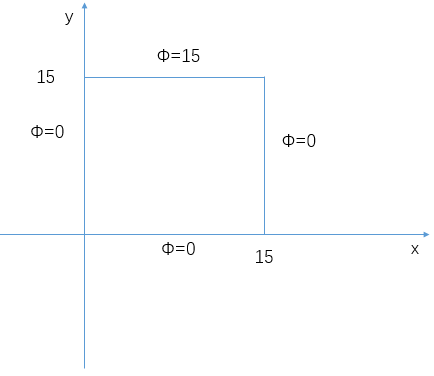

                          图  矩形槽电位分布

2）问题分析与模型的建立

    由电磁学的知识可知，矩形槽中的电位函数$\varphi$满足拉普拉斯方程，即


$$\frac{\partial^2 \varphi }{\partial x^2 }+\frac{\partial^2 \varphi }{\partial y^2 }=0$$


其边界条件满足第一类边界条件（Dirichlet边界条件）


$$\begin{array}{l}
\varphi \left(x,y\right){\left|\right.}_{x=0} =0,\varphi \left(x,y\right){\left|\right.}_{y=0} =0\\
\varphi \left(x,y\right){\left|\right.}_{x=a} =0,\varphi \left(x,y\right){\left|\right.}_{y=b} =100
\end{array}$$


3)模型的求解

对于该问题，可以利用偏微分方程图形求解界面求出该偏微分方程的数值解。这里通过有限差分来近似求解该微分方程。首先推导有限差分法的迭代公式，考查5个相邻节点上电位之间的关系，如下图所示

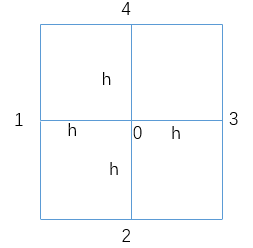

                 图   5点电位分布

设节点0的坐标为$\left(x_0 ,y_0 \right)$,其他的类似。将通过节点0且平行于轴的直线上的相邻点$x$的电位值$\varphi \left(x,y_0 \right)$在节点0处的泰勒展开为


$$\varphi_x =\varphi_0 +\left(\frac{\partial \varphi }{\partial x}\right){\left|\right.}_{x=x_0 } \left(x-x_0 \right)+\frac{1}{2!}\left(\frac{\partial^2 \varphi }{\partial x^2 }\right){\left|\right.}_{x=x_0 } {\left(x-x_0 \right)}^2 +\frac{1}{3!}\left(\frac{\partial^3 \varphi }{\partial x^3 }\right){\left|\right.}_{x=x_0 } {\left(x-x_0 \right)}^3 +\frac{1}{4!}\left(\frac{\partial^4 \varphi }{\partial x^4 }\right){\left|\right.}_{x=x_0 } {\left(x-x_0 \right)}^4 +\cdots$$


在节点1处，$x_1 =x_0 -h$,该点的电位为


$$\varphi_1 =\varphi_0 -\left(\frac{\partial \varphi }{\partial x}\right){\left|\right.}_{x=x_0 } h+\frac{1}{2!}\left(\frac{\partial^2 \varphi }{\partial x^2 }\right){\left|\right.}_{x=x_0 } h^2 -\frac{1}{3!}\left(\frac{\partial^3 \varphi }{\partial x^3 }\right){\left|\right.}_{x=x_0 } h^3 +\frac{1}{4!}\left(\frac{\partial^4 \varphi }{\partial x^4 }\right){\left|\right.}_{x=x_0 } h^4 +\cdots$$


在节点3处，$x_3 =x_0 +h$，该点的电位为


$$\varphi_3 =\varphi_0 +\left(\frac{\partial \varphi }{\partial x}\right){\left|\right.}_{x=x_0 } h+\frac{1}{2!}\left(\frac{\partial^2 \varphi }{\partial x^2 }\right){\left|\right.}_{x=x_0 } h^2 +\frac{1}{3!}\left(\frac{\partial^3 \varphi }{\partial x^3 }\right){\left|\right.}_{x=x_0 } h^3 +\frac{1}{4!}\left(\frac{\partial^4 \varphi }{\partial x^4 }\right){\left|\right.}_{x=x_0 } h^4 +\cdots$$


由以上两式相加可得

${\varphi_1 +\varphi }_3 ={2\varphi }_0 +\left(\frac{\partial^2 \varphi }{\partial x^2 }\right){\left|\right.}_{x=x_0 } h^2 +\frac{2}{4!}\left(\frac{\partial^4 \varphi }{\partial x^4 }\right){\left|\right.}_{x=x_0 } h^4 +\cdots$** （10-21）**

当$h$充分小时，$o\left(h^3 \right)$均可以忽略，则式（10-21）可以近似写成


$${\varphi_1 +\varphi }_3 ={2\varphi }_0 +\left(\frac{\partial^2 \varphi }{\partial x^2 }\right){\left|\right.}_{x=x_0 } h^2$$


同理可以求得


$${\varphi_2 +\varphi }_4 ={2\varphi }_0 +\left(\frac{\partial^2 \varphi }{\partial y^2 }\right){\left|\right.}_{y=y_0 } h^2$$


因此


$${\varphi_1 +\varphi }_3 {{+\varphi }_2 +\varphi }_4 ={4\varphi }_0 +\left(\frac{\partial^2 \varphi }{\partial x^2 }\right){\left|\right.}_{x=x_0 } h^2 +$$

$$\left(\frac{\partial^2 \varphi }{\partial y^2 }\right){\left|\right.}_{y=y_0 } h^2$$


又$\frac{\partial^2 \varphi }{\partial x^2 }+\frac{\partial^2 \varphi }{\partial y^2 }=0$

故


$${\varphi_1 +\varphi }_2 +{\varphi_3 +\varphi }_4 =4\varphi_0$$



$$\varphi_0 =\frac{{\varphi_1 +\varphi }_2 +{\varphi_3 +\varphi }_4 }{4}$$


写成迭代格式有

${\varphi_{\textrm{ij}} }^{\left(k+1\right)} =\frac{1}{4}\left({\varphi_{i-1,j} }^{\left(k\right)} +{\varphi_{i,j-1} }^{\left(k\right)} +{\varphi_{i+1,j} }^{\left(k\right)} +{\varphi_{i,j+1} }^{\left(k\right)} \right)$**       (10-22)**

式（10-22）即为限差分法的迭代公式。

下面回归到题述问题的求解。

先将区域进行分格，用两条水平和垂直的等间距直线将正方形区域划分为9个网格，16个节点，如下图所示。其中边界节点12个，内节点4个，边界节点上的电位是已知的，而4个内节点的电位未知，根据题意，列出如下线性方程组：


$$\begin{array}{l}
\varphi_1 =\left(100+0+\varphi_2 +\varphi_3 \right)/4\\
\varphi_2 =\left(100+0+\varphi_1 +\varphi_4 \right)/4\\
\varphi_3 =\left(0+0+\varphi_1 +\varphi_4 \right)/4\\
\varphi_4 =\left(0+0+\varphi_2 +\varphi_3 \right)/4
\end{array}$$


写成标准的矩阵形式为


$$\left\lbrack \begin{array}{cccc}
4 & -1 & -1 & 0\\
-1 & 4 & 0 & -1\\
-1 & 0 & 4 & -1\\
0 & -1 & -1 & 4
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
\varphi_1 \\
\varphi_2 \\
\varphi_3 \\
\varphi_4 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
100\\
100\\
0\\
0
\end{array}\right\rbrack$$


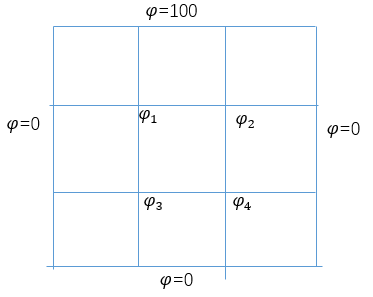

         图  用两条直线划分正方形区域

为了提供求解的精度，需要将网格加密，假设将正方形区域划分为$n\times n\left(n\ge 3\right)$个网格，这时若直接输入矩阵$A$和右端向量$b$则显得非常繁琐。需要分析一下矩阵$A$和右端向量$b$的结构，通过某种途径构造出矩阵$A$和右端向量$b$，再调用Linear_equation函数求解即可。

方法二：迭代求解方法

对于该问题也可以直接根据推导出的迭代公式求解，代码如下：

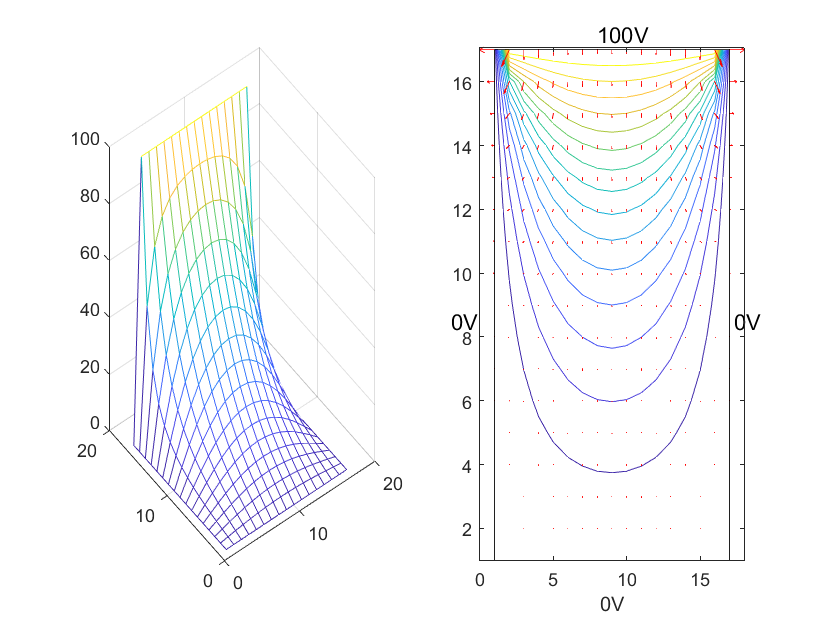

hx=17;hy=hx;   % 设置网格节点数
v1=ones(hy,hx);  % 设置行列二维数组
% 上下两行的Dirichlet边界条件值
v1(hy,:)=ones(1,hx)*100;
v1(1,:)=zeros(1,hx);
% 左右两列的Dirichlet 边界条件值
v1(:,1)=zeros(1,hx);
v1(:,hx)=zeros(1,hx);
v2=v1;err=1;t=0;  % 初始化
while(err>1e-6)  % 由v1迭代，算出v2，迭代精度为1e-6
    for i=2:hy-1   % 从2到hy-1行循环
        for j=2:hx-1   % 从2到hx-1列循环 
            v2(i,j)=(v1(i,j+1)+v1(i+1,j)+v2(i-1,j)+v2(i,j-1))/4;  % 拉普拉斯方程差分式
%             err=max(abs(v2(i,j)-v1(i,j)));
        end
    end
    err=norm(v2(i,j)-v1(i,j));
    v1=v2;
end
subplot(1,2,1),mesh(v2)  % 画三维曲面图
subplot(1,2,2),contour(v2,15)  % 画等电位线图
hold on
x=1:hx;y=1:hy;
[xx,yy]=meshgrid(x,y);  % 形成栅格
[Gx,Gy]=gradient(v2,0.6,0.6);  % 计算梯度
quiver(xx,yy,-Gx,-Gy,0.8,'r')  % 根据梯度数据画箭头
plot([1,1,hx,hx,1],[1,hy,hy,1,1],'k')  % 画导体边框
xlabel('0V','fontsize',11);  % 下标注
text(hx/2-0.5,hy+0.5,'100V','fontsize',11);  % 上标注
text(-2,hy/2,'0V','fontsize',11);  % 左标注
text(hx+0.3,hy/2,'0V','fontsize',11);  % 右标注
hold off

# 作业：

1、求解下面的线性方程组

（1）$\begin{array}{l}
\mathrm{x+2y}+3z+4w=5\\
4x+3y+2z+w=4\\
x+3y+2z+4w=3\\
4x+y+3z+2w=2
\end{array}$

(2)$\begin{array}{l}
x+y-3z-w=1\\
3x-y-3z+4w=4\\
x+5y-9z-8w=0
\end{array}$

2、求解下面给出的线性代数方程组


$$\left\lbrack \begin{array}{cccc}
1 & 2 & 3 & 4\\
4 & 3 & 2 & 1\\
1 & 3 & 2 & 4\\
4 & 1 & 3 & 2
\end{array}\right\rbrack x=\left\lbrack \begin{array}{cc}
5 & 1\\
4 & 2\\
3 & 3\\
2 & 4
\end{array}\right\rbrack$$


3、一种大型输电网络可以简化为下图所示电路，其中$R_i$表示负载电阻，$r_i$表示线路内阻，设电源电压为V。

若$R_i =6\Omega$,$r_i =1\Omega$,V=18V，试求出各个负载上的电流$I_1 ,$$I_2 ,\ldotp \ldotp \ldotp ,I_n$及总电流$I_0$.